# Image Analysis and Computer Vision - Homework Project 2024/25

**Politecnico di Milano - Paolo Riva - 10938975**

#### Theory:

- From the 𝒍𝒊 and 𝒎𝒋 lines, find the vanishing line 𝒍′∞ of the horizontal plane.

- Using the results of the previous point, find a (Euclidean) rectification mapping 𝑯𝑹 for a horizontal plane (e.g., the lower horizontal face of the parallelepiped), and compute the depth 𝒎 of the parallelepiped.

- From the results of the previous points, use the lines 𝒉𝒊 to find the calibration matrix ***K***.

- Using the results of the previous points, determine the height 𝒉 of the parallelepiped.

- Using 𝑺 and the results of previous points, compute the X-Y coordinates of a dozen points (at your choice) of the unknown horizontal curve.

- Using ***K***, localize the camera with respect to the parallelepiped.

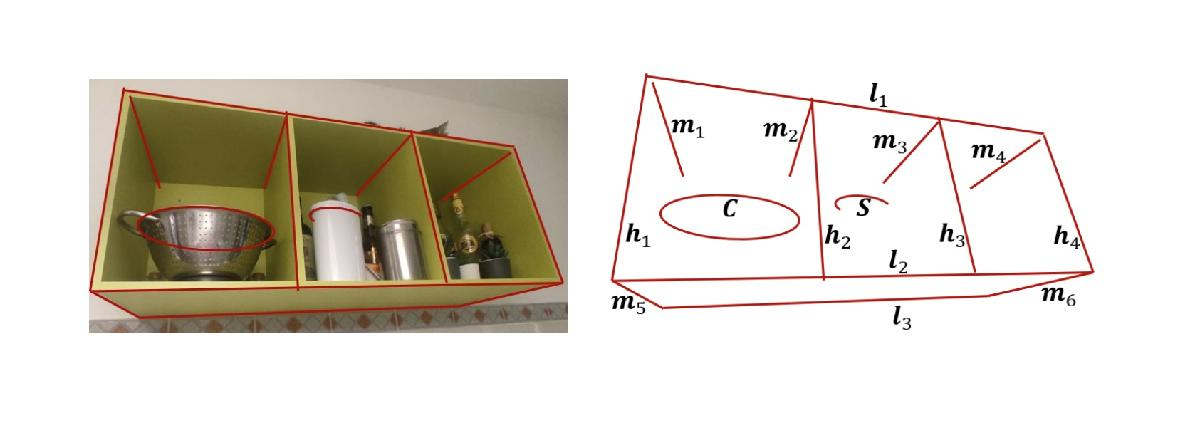

#### Matlab:

- Consider the image Look-outCat.png. Using feature extraction techniques plus possible manual intervention, extract the images of useful lines and both the image 𝑪, of the circumference and the image 𝑺 of the other planar curve.

- Write a Matlab program that implements the solutions to problems 1 – 6 and show the obtained results.

- Plot the rectified curve 𝑺 and show different views of the recovered 3D model of the rectangular parallelepiped.

## 1 Feature Extraction

clc; clear all; close all;

% Load the image
image = imread('Look-outCat.jpg');
[height, width, ~] = size(image); 

### Lines *l_i*

%%% Line "l" detection %%%

% Display the image
imshow(image);
hold on;

% Number of lines to extract
num_lines = input('Enter the number of lines l to extract: ');

% Initialize matrix to store homogeneous line equations
lines_homogeneous_l = zeros(3, num_lines);

for i = 1:num_lines
    fprintf('Select two points for line %d\n', i);
    
    % Select two points using ginput
    [x, y] = ginput(2);
    plot(x, y, 'r-o', 'LineWidth', 2); % Show selected points on the image
    
    % Homogeneous coordinates of the points
    p1 = [x(1); y(1); 1];
    p2 = [x(2); y(2); 1];
    
    % Compute the line equation (cross product of points)
    line_h = cross(p1, p2);
    
    % Normalize the line equation
    line_h = line_h / (line_h(3));
    
    % Store the line equation
    lines_homogeneous_l(:, i) = line_h;
    
    fprintf('Line %d equation in homogeneous coordinates: [%f, %f, %f]\n', ...
        i, line_h(1), line_h(2), line_h(3));
    
    close all;
    imshow(image);
    hold on;

    %% Plot the line on the image
    % Find intersection points with the image boundaries
    [height, width, ~] = size(image);
    
    % Image boundaries as lines in homogeneous coordinates
    top_boundary = [0, 1, 0];              % y = 0
    bottom_boundary = [0, 1, -height];     % y = height
    left_boundary = [1, 0, 0];             % x = 0
    right_boundary = [1, 0, -width];       % x = width
    
    % Intersections of the line with the boundaries
    top_intersection = cross(line_h, top_boundary);
    bottom_intersection = cross(line_h, bottom_boundary);
    left_intersection = cross(line_h, left_boundary);
    right_intersection = cross(line_h, right_boundary);
    
    % Normalize to convert to Cartesian coordinates
    top_intersection = top_intersection / top_intersection(3);
    bottom_intersection = bottom_intersection / bottom_intersection(3);
    left_intersection = left_intersection / left_intersection(3);
    right_intersection = right_intersection / right_intersection(3);
    
    text(100,100,sprintf('line (l): l%d', i),'FontSize',18,'Color','b')
    %text(right_intersection(1),right_intersection(2),'right_1','FontSize',28,'Color','b')
    plot([left_intersection(1),right_intersection(1)],[left_intersection(2),right_intersection(2)],'LineWidth',3)

end

% Save the line equations to a .mat file for further use
save('lines_homogeneous_l.mat', 'lines_homogeneous_l');
disp('Line equations saved to lines_homogeneous.mat');

### Lines *m_j*

%%% Line "m" detection %%%

% Display the image
imshow(image);
hold on;

% Number of lines to extract
num_lines = input('Enter the number of lines m to extract: ');

% Initialize matrix to store homogeneous line equations
lines_homogeneous_m = zeros(3, num_lines);

for i = 1:num_lines
    fprintf('Select two points for line %d\n', i);
    
    % Select two points using ginput
    [x, y] = ginput(2);
    plot(x, y, 'r-o', 'LineWidth', 2); % Show selected points on the image
    
    % Homogeneous coordinates of the points
    p1 = [x(1); y(1); 1];
    p2 = [x(2); y(2); 1];
    
    % Compute the line equation (cross product of points)
    line_h = cross(p1, p2);
    
    % Normalize the line equation
    line_h = line_h / (line_h(3));
    
    % Store the line equation
    lines_homogeneous_m(:, i) = line_h;
    
    fprintf('Line %d equation in homogeneous coordinates: [%f, %f, %f]\n', ...
        i, line_h(1), line_h(2), line_h(3));
    
    close all;
    imshow(image);
    hold on;

    % Plot the line on the image
    % Find intersection points with the image boundaries
    [height, width, ~] = size(image);
    
    % Image boundaries as lines in homogeneous coordinates
    top_boundary = [0, 1, 0];              % y = 0
    bottom_boundary = [0, 1, -height];     % y = height
    left_boundary = [1, 0, 0];             % x = 0
    right_boundary = [1, 0, -width];       % x = width
    
    % Intersections of the line with the boundaries
    top_intersection = cross(line_h, top_boundary);
    bottom_intersection = cross(line_h, bottom_boundary);
    left_intersection = cross(line_h, left_boundary);
    right_intersection = cross(line_h, right_boundary);
    
    % Normalize to convert to Cartesian coordinates
    top_intersection = top_intersection / top_intersection(3);
    bottom_intersection = bottom_intersection / bottom_intersection(3);
    left_intersection = left_intersection / left_intersection(3);
    right_intersection = right_intersection / right_intersection(3);
    
    text(100,100,sprintf('line (m): m%d', i),'FontSize',18,'Color','b')
    plot([left_intersection(1),right_intersection(1)],[left_intersection(2),right_intersection(2)],'LineWidth',3)

end

% Save the line equations to a .mat file for further use
save('lines_homogeneous_m.mat', 'lines_homogeneous_m');
disp('Line equations saved to lines_homogeneous.mat');


### Lines *h_i*

%%% Line "h" detection %%%

% Display the image
imshow(image);
hold on;

% Number of lines to extract
num_lines = input('Enter the number of lines m to extract: ');

% Initialize matrix to store homogeneous line equations
lines_homogeneous_h = zeros(3, num_lines);

for i = 1:num_lines
    fprintf('Select two points for line %d\n', i);
    
    % Select two points using ginput
    [x, y] = ginput(2);
    plot(x, y, 'r-o', 'LineWidth', 2); % Show selected points on the image
    
    % Homogeneous coordinates of the points
    p1 = [x(1); y(1); 1];
    p2 = [x(2); y(2); 1];
    
    % Compute the line equation (cross product of points)
    line_h = cross(p1, p2);
    
    % Normalize the line equation
    line_h = line_h / (line_h(3));
    
    % Store the line equation
    lines_homogeneous_h(:, i) = line_h;
    
    fprintf('Line %d equation in homogeneous coordinates: [%f, %f, %f]\n', ...
        i, line_h(1), line_h(2), line_h(3));
    
    close all;
    imshow(image);
    hold on;

    % Plot the line on the image
    % Find intersection points with the image boundaries
    [height, width, ~] = size(image);
    
    % Image boundaries as lines in homogeneous coordinates
    top_boundary = [0, 1, 0];              % y = 0
    bottom_boundary = [0, 1, -height];     % y = height
    left_boundary = [1, 0, 0];             % x = 0
    right_boundary = [1, 0, -width];       % x = width
    
    % Intersections of the line with the boundaries
    top_intersection = cross(line_h, top_boundary);
    bottom_intersection = cross(line_h, bottom_boundary);
    left_intersection = cross(line_h, left_boundary);
    right_intersection = cross(line_h, right_boundary);
    
    % Normalize to convert to Cartesian coordinates
    top_intersection = top_intersection / top_intersection(3);
    bottom_intersection = bottom_intersection / bottom_intersection(3);
    left_intersection = left_intersection / left_intersection(3);
    right_intersection = right_intersection / right_intersection(3);
    
    text(100,100,sprintf('line (h): h%d', i),'FontSize',18,'Color','b')
    plot([left_intersection(1),right_intersection(1)],[left_intersection(2),right_intersection(2)],'LineWidth',3)

end

% Save the line equations to a .mat file for further use
save('lines_homogeneous_h.mat', 'lines_homogeneous_h');
disp('Line equations saved to lines_homogeneous.mat');


### Conic *C*

% Note: select exactly 6 points

% Number of conics to extract
num_conics = 1;

% Initialize a cell array to store conic matrices
conics = cell(1, num_conics);
imshow(image);
hold on;


% Data input: enter five points (then enter)
disp('click 5 points, then enter');
[x, y]=getpts;
scatter(x,y,100,'filled');

%%
% x and y are now column vectors.
x
y

%% Estimation of conic parameters
% using the technique shown in "Multiple View Geometry", page 9.
% this is equivalent to requiring that the conic passes trhough all the six
% points
A = [x.^2 x.*y y.^2 x y ones(size(x))]

% A is 5x6: we find the parameter vector (containing [a b c d e f]) as the
% right null space of A.
% This returns a vector N such that A*N=0.  Note that this expresses the
% fact that the conic passes through all the points we inserted.
N = null(A);
% alternatively you can use the svd
[~,~,V] = svd(A); 
N = V(:,end);
%%
% Let's assign the values to variables and build the 3x3 conic matrix
% (which is symmetrical)
cc = N(:, 1);
% change the name of variables
[a b c d e f] = deal(cc(1),cc(2),cc(3),cc(4),cc(5),cc(6));
% here is the matrix of the conic: off-diagonal elements must be divided
% by two
C=[a b/2 d/2; b/2 c e/2; d/2 e/2 f]
conics{1} = C;
% Remark: since the right null space has dimension one,
% when the points are taken in general position
% the system admits an infinite number of solutions
% however, these can be expressed as lambda * n, where n 
% lambda \in R and n = null(A). 
% thus, they all corresponds to the same conic.

close all;
imshow(image);
hold on;

%% Plotting C on the image
for i=1:1200
    for j=1:1600
        im_four1(i,j)=[j i 1]*conics{1}*[j i 1]';
    end
end

% plot(im_four1<0);
% hold on;
% scatter(x(1 : 5), y(1 : 5), 100, 'filled','cyan');
% scatter(x(6), y(6), 100, 'filled','red');
% title('1st nullspace col ')

% Define image grid
[x_grid, y_grid] = meshgrid(1:width, 1:height); % Create a grid of pixel coordinates

% Evaluate the conic equation at each point of the grid
conic_values = a * x_grid.^2 + b * x_grid .* y_grid + c * y_grid.^2 + d * x_grid + e * y_grid + f;

% Plot the boundary of the conic where the conic equation equals zero
hold on;
contour(x_grid, y_grid, conic_values, [0, 0], 'LineWidth', 2, 'Color', 'red');

% Highlight the points used for conic estimation
scatter(x(1:6), y(1:6), 100, 'filled', 'red'); % Points in cyan

% Display the result
title('Detected Conic Overlay');
hold off;

% Save the conics to a .mat file for further use
save('conics.mat', 'conics');
disp('Conic matrices saved to conics.mat');
% close all;

### Curve *S*

% Display the image and collect 12 points
imshow(image);
hold on;
disp('Click 12 points on the curve, then press Enter.');
[x, y] = getpts; % Collect 12 points
scatter(x, y, 100, 'filled', 'blue'); % Show the points on the image

% Check if we have 12 points
if length(x) > 12
    % Truncate to the last 12 points
    x = x(end-11:end);
    y = y(end-11:end);
    disp('More than 12 points selected. Truncating to the last 12 points.');
elseif length(x) < 12
    error('You must select at least 12 points.');
end

% Store the points in a 12x3 matrix in homogeneous coordinates
curve_s = [x, y, ones(size(x))];

% Save the points to a .mat file
save('curves.mat', 'curve_s');
disp('Points in homogeneous coordinates saved to curves.mat');

% % Perform spline interpolation
% x_dense = linspace(min(x), max(x), 500); % Fine-grained x values
% y_dense = spline(x, y, x_dense);        % Spline interpolation for dense x
% 
% % Overlay the interpolated curve on the image
% plot(x_dense, y_dense, 'r-', 'LineWidth', 2); % Red spline curve
% title('Spline Interpolation of Selected Points');
% hold off;

### 2.1 Vanishing Line l_inf

clc; close all; clear all;
% Load extracted data from previous sections (lines, conics, curves)
load("lines_homogeneous_l.mat"); % 3x3 (coords x lines l_i)
load("lines_homogeneous_m.mat"); % 3x6 (coords x lines m_j)
load("lines_homogeneous_h.mat"); % 3x4 (coords x lines h_i)
load("conics.mat"); % 
load("curves.mat"); % 12 Points of Curve S
% Load the image
image = imread('Look-outCat.jpg');
[height, width, ~] = size(image); 

% Input: lines_homogeneous_l (3x3), lines_homogeneous_m (3x6)
% Extract the relevant lines from the input matrices
l1 = lines_homogeneous_l(:, 1); % First line from l
l3 = lines_homogeneous_l(:, 3); % Third line from l

m1 = lines_homogeneous_m(:, 1); % First line from m
m6 = lines_homogeneous_m(:, 6); % Sixth line from m

% Calculate vanishing points
v_l1_l3 = cross(l1, l3); % Vanishing point from l1 and l3
v_m1_m6 = cross(m1, m6); % Vanishing point from m1 and m6

% Normalize the vanishing points (homogeneous coordinates)
v_l1_l3 = v_l1_l3 / v_l1_l3(3);
v_m1_m6 = v_m1_m6 / v_m1_m6(3);

% Calculate the vanishing line l_inf
l_inf = cross(v_l1_l3, v_m1_m6);

% Normalize the vanishing line (homogeneous coordinates)
l_inf = l_inf / l_inf(3);

% Display results
disp('Vanishing point from l1 and l3:');

Vanishing point from l1 and l3:


disp(v_l1_l3);

   1.0e+03 *

    3.3311
    0.6672
    0.0010




disp('Vanishing point from m1 and m6:');

Vanishing point from m1 and m6:


disp(v_m1_m6);

  595.6985
  874.3362
    1.0000




disp('Vanishing line (l_inf):');

Vanishing line (l_inf):


disp(l_inf);

   -0.0001
   -0.0011
    1.0000



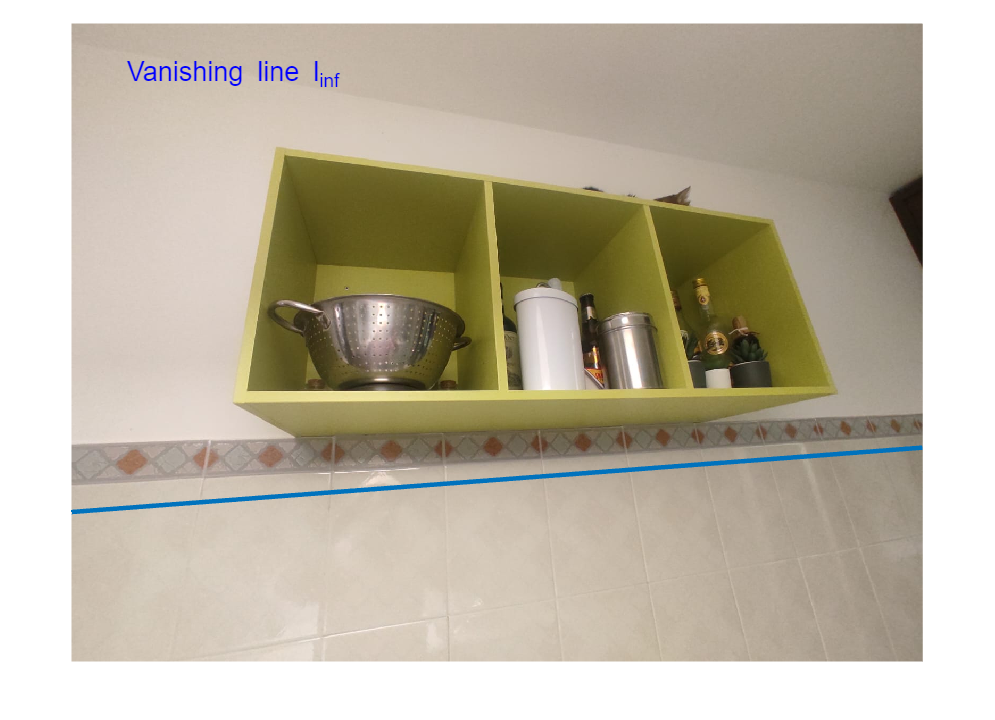


close all;
imshow(image);
hold on;

% Plot the line on the image
% Find intersection points with the image boundaries
[height, width, ~] = size(image);

% Image boundaries as lines in homogeneous coordinates
top_boundary = [0, 1, 0];              % y = 0
bottom_boundary = [0, 1, -height];     % y = height
left_boundary = [1, 0, 0];             % x = 0
right_boundary = [1, 0, -width];       % x = width

% Intersections of the line with the boundaries
top_intersection = cross(l_inf, top_boundary);
bottom_intersection = cross(l_inf, bottom_boundary);
left_intersection = cross(l_inf, left_boundary);
right_intersection = cross(l_inf, right_boundary);

% Normalize to convert to Cartesian coordinates
top_intersection = top_intersection / top_intersection(3);
bottom_intersection = bottom_intersection / bottom_intersection(3);
left_intersection = left_intersection / left_intersection(3);
right_intersection = right_intersection / right_intersection(3);

text(100,100,sprintf('Vanishing line l_inf', i),'FontSize',18,'Color','b')
plot([left_intersection(1),right_intersection(1)],[left_intersection(2),right_intersection(2)],'LineWidth',3)

## Standard Rectification matrix with infinity line

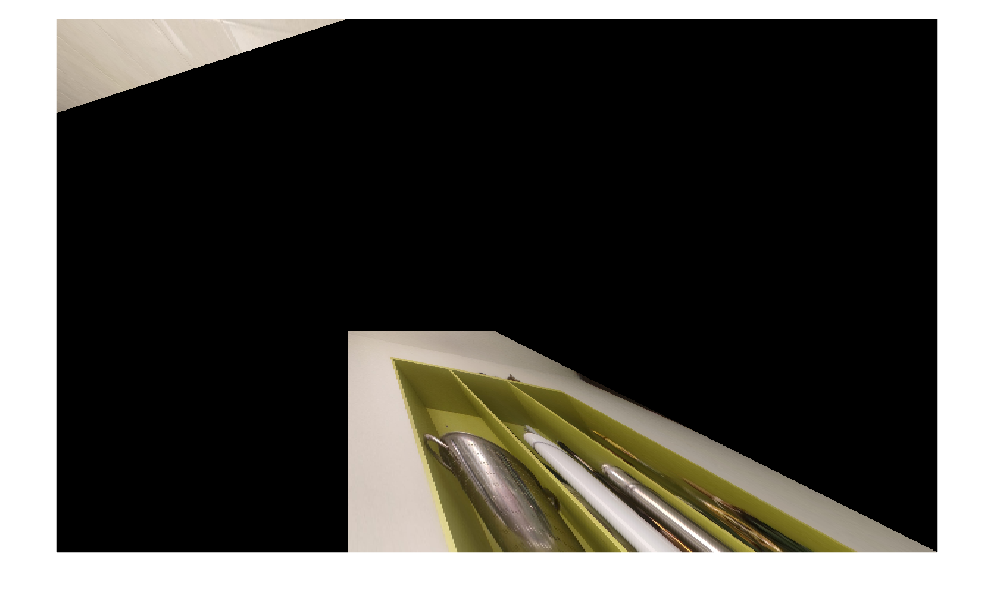

H = [eye(2), zeros(2,1); l_inf(:)'];
tform = projective2d(H');
J = imwarp(image,tform);

figure();
imshow(J);

% clc; close all; clear all;
% 
% % Load extracted data from previous sections
% load("lines_homogeneous_l.mat"); 
% load("lines_homogeneous_m.mat");
% load("lines_homogeneous_h.mat");
% load("conics.mat");
% load("curves.mat");

% Load the image
image = imread('Look-outCat.jpg');
[height, width, ~] = size(image);

% Solve for rectification mapping H_R
syms x y;
a1 = conics{1,1}(1,1)

a1 = -3.5230e-07

b1 = conics{1,1}(2,2)

b1 = -2.9559e-06

c1 = conics{1,1}(3,3)

c1 = -1.0000

d1 = conics{1,1}(1,2)

d1 = 8.5044e-08

e1 = conics{1,1}(2,3)

e1 = 0.0016

f1 = conics{1,1}(1,3)

f1 = 1.5592e-04

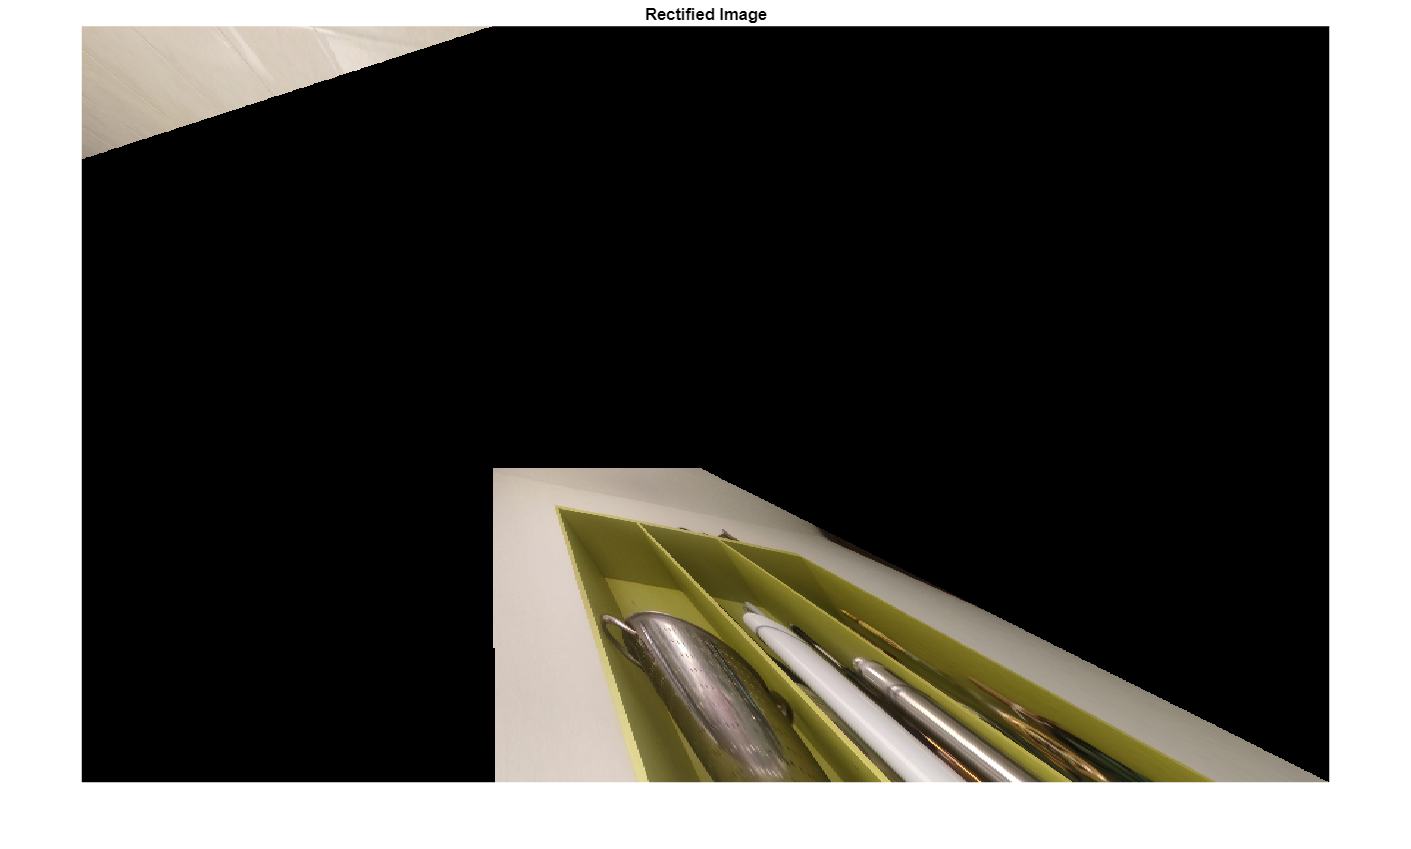


% Conic equation and line at infinity
eq1 = a1*x^2 + b1*x*y + c1*y^2 + d1*x + e1*y + f1;
eq2 = l_inf(1)*x + l_inf(2)*y + l_inf(3);

% Solve the equations
eqns = [eq1 == 0, eq2 == 0];
S12 = solve(eqns, [x, y], 'IgnoreAnalyticConstraints', true, 'MaxDegree', 4);

% Extract the intersection points (two circular points)
s1 = [double(S12.x(1)); double(S12.y(1)); 1];
s2 = [double(S12.x(2)); double(S12.y(2)); 1];
II = s1;
JJ = s2;

% Compute the image of the dual conic to principal points
imDCCP = II * JJ' + JJ * II';
imDCCP = imDCCP ./ norm(imDCCP); % Normalize

% Compute the rectifying homography
H = [eye(2), zeros(2, 1); l_inf']; % Homography matrix
tform = projective2d(H'); % Define the transformation
J = imwarp(image, tform); % Apply transformation

% Show the rectified image
figure;
imshow(J);
title('Rectified Image');


% Compute geometric properties from conics
Q = inv(H)' * conics{1,1} * inv(H); % Transform conic
Q = Q ./ Q(3,3); % Normalize

% Convert the conic coefficient to geometric parameters
par_geo = AtoG([Q(1,1), 2*Q(1,2), Q(2,2), 2*Q(1,3), 2*Q(2,3), Q(3,3)]);
center = par_geo(1:2);
axes = par_geo(3:4);
angle = par_geo(5);

% Show rectified conic properties
disp('Rectified conic center:');

Rectified conic center:


disp(center);

   1.0e+03 *

    1.8109
    1.7745



disp('Rectified conic axes:');

Rectified conic axes:


disp(axes);

  772.1561
  325.0963



disp('Rectified conic angle:');

Rectified conic angle:


disp(angle);

    0.5707




% Compute the affinity to make ellipse axes equal
alpha = angle;
a = axes(1);
b = axes(2);

% Rotation matrix
U = [cos(alpha), -sin(alpha); sin(alpha), cos(alpha)];
% Scaling matrix
S = diag([1, a / b]);
% Final affinity matrix
K = U * S * U';
A = [K zeros(2, 1); 0 0 1];
T = A * H; % Composition of transformations

T =     0.1401   -0.0625         0
   -0.0625    0.1974         0
   -0.0000   -0.0001    0.1000


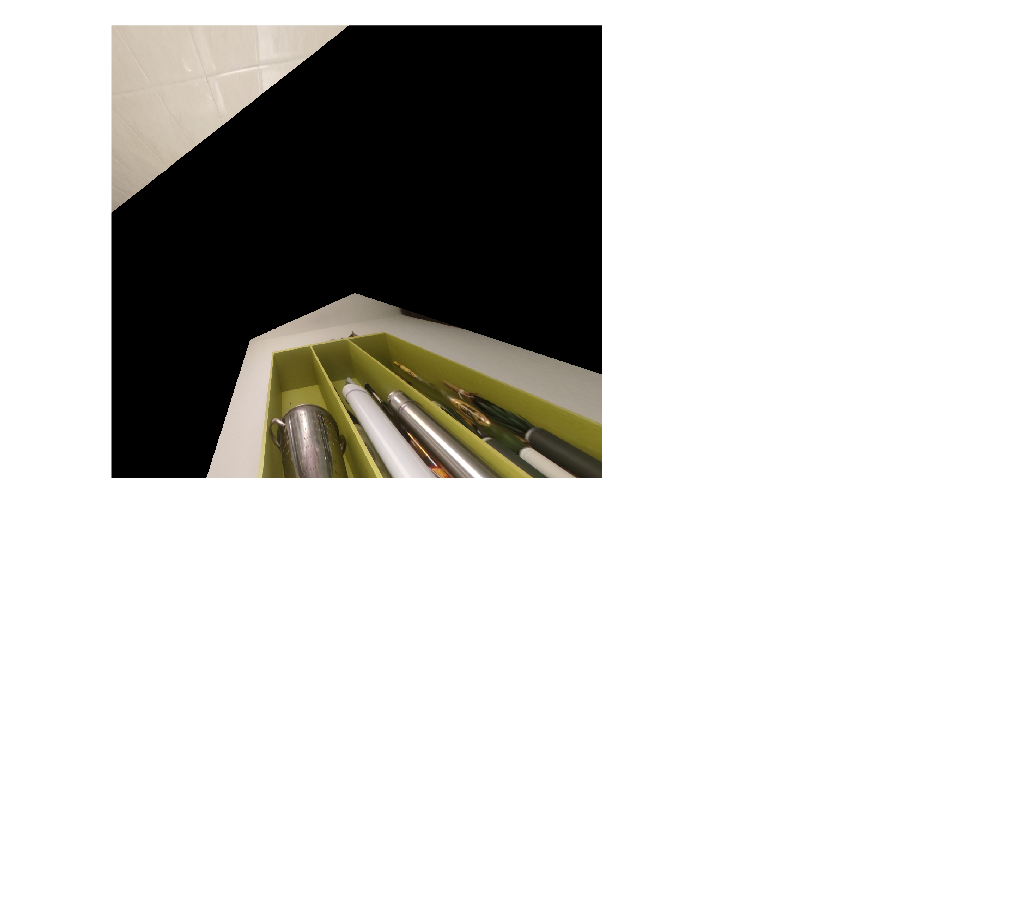

% Apply the final transformation
tform_final = projective2d(T');
J_final = imwarp(image, tform_final);

% Display final rectified image
J_final = imwarp(image, tform_final);

% Display the transformed image
figure('Position', [100, 100, 1200, 1200]); % Adjust figure window size if needed
imshow(J_final);

% Set the x-axis and y-axis limits
xlim([1, 20000]);
ylim([1, 20000]);


% figure;
% imshow(J_final);
% title('Metric Rectification');


